% Read Data

% Running time = 10 * 60 (10 hours)
% Runs per row = 100

DATA = readmatrix("data.csv");  % 1000, 30

%DATA = DATA(1:500,:);

avg_arrivals = DATA(:,1);
avg_served = DATA(:,2);

avg_delay = DATA(:,3);
avg_delay_regular = DATA(:,4);
avg_delay_service = DATA(:,5);
avg_queue_length = DATA(:,6);
avg_queue_NE_length = DATA(:,7);

% NE
avg_queue1_length = DATA(:,8);
avg_queue2_length = DATA(:,9);
avg_queue3_length = DATA(:,10);
avg_queue4_length = DATA(:,11);
avg_queue5_length = DATA(:,12);
avg_queue6_length = DATA(:,13);

avg_queue1_open = DATA(:, 14);
avg_queue2_open = DATA(:, 15);
avg_queue3_open = DATA(:, 16);
avg_queue4_open = DATA(:, 17);
avg_queue5_open = DATA(:, 18);
avg_queue6_open = DATA(:, 19);

avg_queue_opentimes = [mean(avg_queue1_open) mean(avg_queue2_open) mean(avg_queue3_open) mean(avg_queue4_open) mean(avg_queue5_open) mean(avg_queue6_open)];

% Confidence intervals
[ci_delay_lower, ci_delay_upper] = tConfidenceInterval(avg_delay, 0.05);
[ci_delay_regular_lower, ci_delay_regular_upper] = tConfidenceInterval(avg_delay_regular, 0.05);
[ci_delay_service_lower, ci_delay_service_upper] = tConfidenceInterval(avg_delay_service, 0.05);
[ci_queue_length_lower, ci_queue_length_upper] = tConfidenceInterval(avg_queue_length, 0.05);

a = 1.9837

b = 2.0013

m = 1.9925

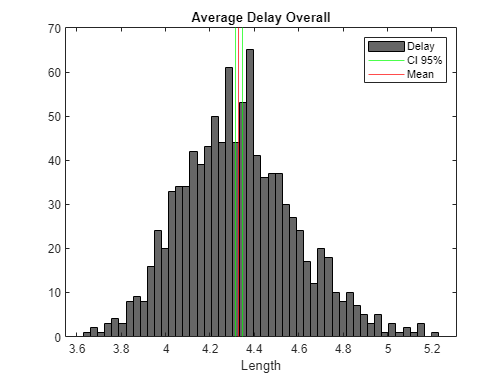

histCI(avg_delay, "Average Delay Overall");

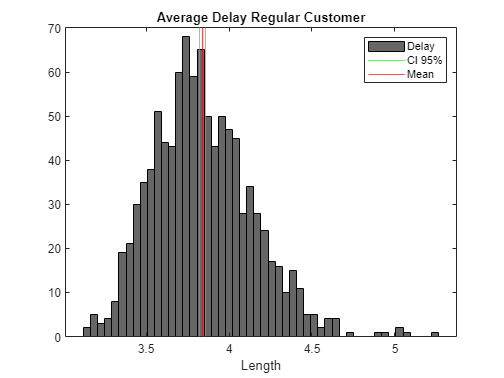


histCI(avg_delay_regular, "Average Delay Regular Customer");

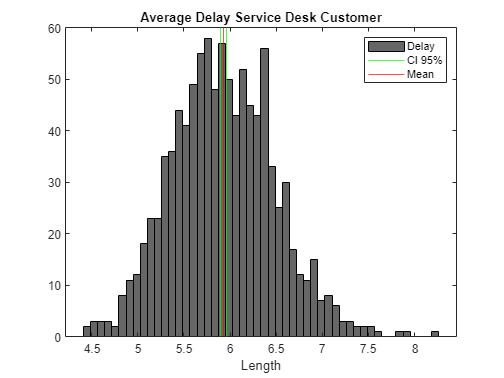


histCI(avg_delay_service, "Average Delay Service Desk Customer");

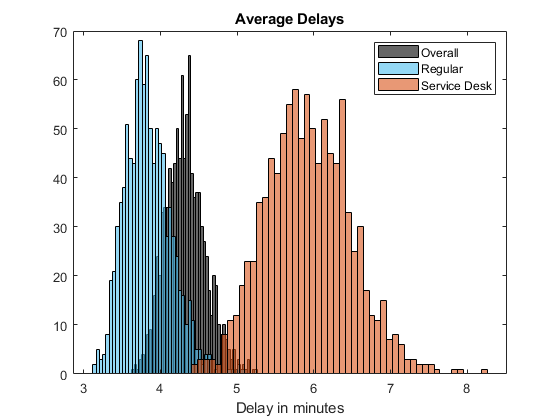



figure(50);
histogram(avg_delay, 50, 'FaceColor', 'black');
title("Average Delays");
xlabel("Delay in minutes");
hold on;
histogram(avg_delay_regular, 50, 'FaceColor', '[0.3010 0.7450 0.9330]');
hold on;
histogram(avg_delay_service, 50, 'FaceColor', '[0.8500 0.3250 0.0980]');
legend(["Overall","Regular","Service Desk"])
hold off;

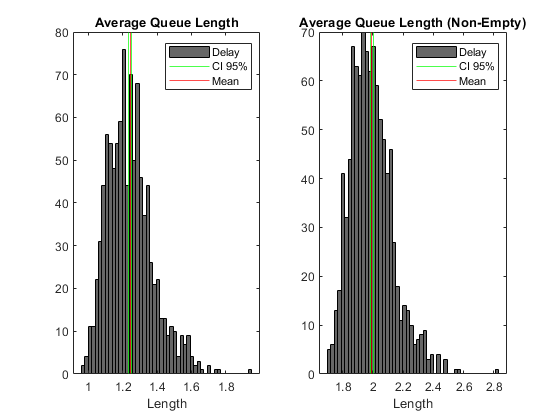


figure(183);
subplot(1,2,1);
histCI(avg_queue_length, "Average Queue Length");
subplot(1,2,2);
histCI(avg_queue_NE_length, "Average Queue Length (Non-Empty)");

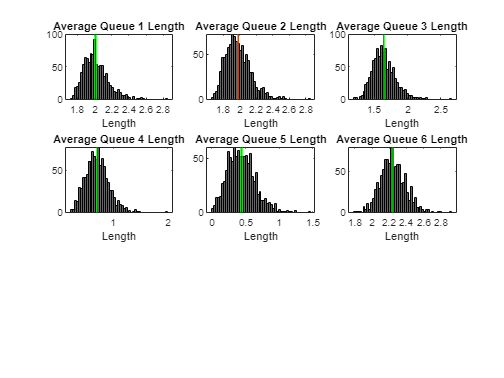

figure(1);
subplot(3,3,1);
histCI_noLegend(avg_queue1_length, "Average Queue 1 Length");
subplot(3,3,2);
histCI_noLegend(avg_queue2_length, "Average Queue 2 Length");
subplot(3,3,3);
histCI_noLegend(avg_queue3_length, "Average Queue 3 Length");
subplot(3,3,4);
histCI_noLegend(avg_queue4_length, "Average Queue 4 Length");
subplot(3,3,5);
histCI_noLegend(avg_queue5_length, "Average Queue 5 Length");
subplot(3,3,6);
histCI_noLegend(avg_queue6_length, "Average Queue 6 Length");

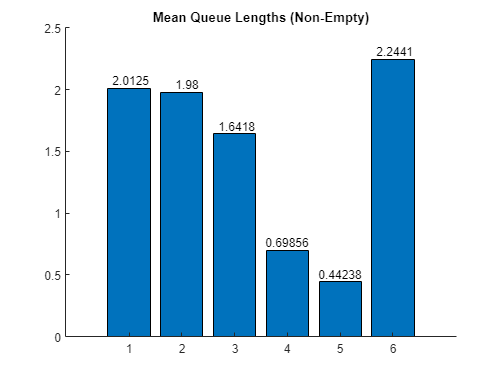


figure(2);
Y = [mean(avg_queue1_length) mean(avg_queue2_length) mean(avg_queue3_length) mean(avg_queue4_length) mean(avg_queue5_length) mean(avg_queue6_length)];
bar(Y);
title("Mean Queue Lengths (Non-Empty)")
text(1:length(Y),Y,num2str(Y'),'vert','bottom','horiz','center');
box off;

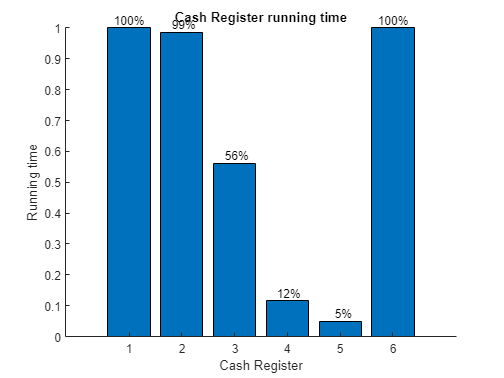

% Queue run time
figure(3);
bar(avg_queue_opentimes);
text(1:length(avg_queue_opentimes),avg_queue_opentimes,num2str((round(avg_queue_opentimes,2)*100)')+"%",'vert','bottom','horiz','center'); 
xlabel("Cash Register");
ylabel("Running time");
title("Cash Register running time");
box off;

function [a, b] = tConfidenceInterval(data, alpha)
    n = length(data);
    dof = n-1;
    t = tinv(1-alpha/2,dof);

    var = sum((data-mean(data)).^2)/dof;
    a = mean(data) - t*sqrt(var/n);
    b = mean(data) + t*sqrt(var/n);
end

% Plots a histogram of a data with lines for the confidence interval and
% mean
function [] = histCI(data, name)
    %figure(name);
    [a, b] = tConfidenceInterval(data, 0.05);
    p1 = histogram(data, 50, 'FaceColor', 'black');
    title(name);
    xlabel("Length");
    hold on;
    p2 = xline(a, 'Color', 'g');
    hold on;
    p3 = xline(b, 'Color', 'g');
    hold on;
    p4 = xline(mean(data), 'Color', 'r');
    %t = text(min(data),30, '\leftarrow CI: ' + string(a) + " to " + string(b));
    %t.Color = 'red';
    h = [p1,p2,p4];
    legend(h, "Delay","CI 95%","Mean");
    hold off;
end

% Plots a histogram of a data with lines for the confidence interval and
% mean, but without legend
function [] = histCI_noLegend(data, name)
    %figure(name);
    [a, b] = tConfidenceInterval(data, 0.05);
    p1 = histogram(data, 50, 'FaceColor', 'black');
    title(name);
    xlabel("Length");
    hold on;
    p2 = xline(a, 'Color', 'g');
    hold on;
    p3 = xline(b, 'Color', 'g');
    hold on;
    p4 = xline(mean(data), 'Color', 'r');
    hold off;
end